**This program assumes an known map state. Code prompts user to input a selection of available excel grid maps. Generates a neural activity matrix of the same size as the selected map. Updates entire neural activity level for each grid in the map, and uses heuristic method for path selection. **

clear 
clc

select = input('1-Rectangle obstacle, 2-Circular, 3-Generic, 4-100 park map: ')

select = 3

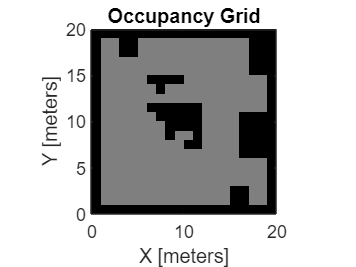


if select == 1
    env = readmatrix("map builder.xlsx", "Sheet","Rectangle obstacle");
elseif select == 2
    env = readmatrix("map builder.xlsx", "Sheet","Circular obstacle");
elseif select == 3
    env = readmatrix("map builder.xlsx", "Sheet","test");
elseif select == 4
    env = readmatrix("map builder.xlsx", "Sheet","100 park");
end 

map = occupancyMap(env);
n = zeros(map.GridSize(1), map.GridSize(2)); %generate array to store neural activity values
mat = occupancyMatrix(map); %an array containing the actual values of each grid in the occupancy map
show(map)

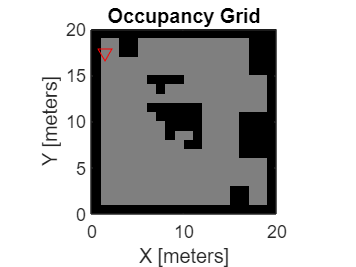

%initialize starting location
up_dir = '^r'; %indicator for robot heading direction on map
down_dir = 'vr'; %indicator for robot heading direction on map
left_dir = '<r'; 
right_dir = '>r';
hold on
startloc = [3,2]; %starting grid location
xy = grid2world(map,[startloc(1),startloc(2)]); %convert starting grid location to xy coordinates
plot(xy(1), xy(2), down_dir) %plot starting location xy coordinates on map

pc = startloc; %initialize starting grid location as current position

%go = input('press 1 to advance... '); %manually simulating motion (for debugging purposes)



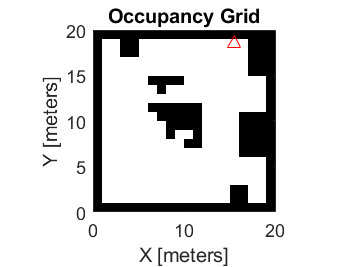

go = 1; %waitforbuttonpress; %CHANGEE!!!
tic
while go == 1 
%for go = 1:500
%Building neural network of map
for j = 1:1:map.GridSize(2) %{Reference; j is cols (goes left to right)}
    for i = 1:1:map.GridSize(1)  %{Reference; i is rows (goes up and down)}
        ab = grid2world(map, [i,j]); %current grid position for neural activity calculation
        status = checkOccupancy(map, [ab(1),ab(2)]); %check status of current grid position
        %convert grid values to 'I' values
        if status == -1
            I = 100;
        elseif status == 0
            I = 0;
        else
            I = -100; 
        end
        I_plus = max([I 0]);
        I_neg = max([-1*I 0]);
        
        %check neural activity level of neighboring neurons, evaluate using ReLu, and calcuate euclidean distance
        try
            North = max([n(i-1, j) 0]); %North = max([n(i, j-1) 0]);
            dNorth = 0.7/((norm(ab - grid2world(map, [i-1, j])))); %dNorth = norm(ab - grid2world(map, [i, j-1]));
        catch
            North = 0;
            dNorth = 0;
        end 

        try
            South = max([n(i+1, j) 0]); %South = max([n(i, j+1) 0]);
            dSouth = 0.7/(norm(ab - grid2world(map, [i+1, j]))); %dSouth = norm(ab - grid2world(map, [i, j+1]));
        catch
            South = 0;
            dSouth = 0;
        end 

        try
            West = max([n(i, j-1) 0]); %West = max([n(i-1, j) 0]);   
            dWest  = 0.7/(norm(ab - grid2world(map, [i, j-1]))); %dWest  = norm(ab - grid2world(map, [i-1, j]));
        catch
            West = 0;
            dWest = 0;
        end 

        try
            East = max([n(i, j+1) 0]); %East = max([n(i+1, j) 0]);   
            dEast = 0.7/(norm(ab - grid2world(map, [i, j+1]))); %dEast = norm(ab - grid2world(map, [i+1, j]));
        catch
            East = 0;
            dEast = 0;
        end 

        try
            NW = max([n(i-1, j-1) 0]); %NW = max([n(i-1, j-1) 0]);
            dNW = 0.7/(norm(ab - grid2world(map, [i-1, j-1]))); %dNW = norm(ab - grid2world(map, [i-1, j-1]));
        catch
            NW = 0;
            dNW = 0;
        end 

        try
            NE = max([n(i-1, j+1) 0]); %NE = max([n(i+1, j-1) 0]);
            dNE = 0.7/(norm(ab - grid2world(map, [i-1, j+1]))); %dNE = norm(ab - grid2world(map, [i+1, j-1]));
        catch
            NE = 0;
            dNE = 0;
        end 

        try
            SW = max([n(i+1, j-1) 0]); %SW = max([n(i-1, j+1) 0]);
            dSW = 0.7/(norm(ab - grid2world(map, [i+1, j-1]))); %dSW = norm(ab - grid2world(map, [i-1, j+1]));
        catch
            SW = 0;
            dSW = 0;
        end 

        try
            SE = max([n(i+1, j+1) 0]); %SE = max([n(i+1, j+1) 0]);
            dSE = 0.7/(norm(ab - grid2world(map, [i+1, j+1]))); %dSE = norm(ab - grid2world(map, [i+1, j+1]));
        catch
            SE = 0;
            dSE = 0;
        end
        
        
        %store evaluated neural activity values for neighboring neurons (8x1 matrix/array)
        xplus = [North, South, West, East, NW, NE, SW, SE];
        
        %store euclidean distances (1x8 matrix/array)
        wij = [dNorth; dSouth; dWest; dEast; dNW; dNE; dSW; dSE];
        
        %calculate the weight
        weight = xplus * wij; % Matrix operation calculating for the weight (order of operation should not be changed)
        
        %set variables
        A = 80;
        B = 1;
        D = 1;
        %define & evaluate equation using ODE solver 
        eqn = @(t,Xi) ((-A*Xi) + (B-Xi)*(I_plus + weight) - (D+Xi)*I_neg);
        [t,Xi] = ode45(eqn, [0:1], n(i,j));
        n(i,j) = Xi(end);

%         if Xi(end) < 0
%             n(i,j) = -0.6;%min(Xi);
%         elseif Xi(end) > 0.5
%             n(i,j) = 0.6;%max(Xi);
%         elseif (Xi(end) > 0) && (Xi(end) < 0.5)  
%             n(i,j) = 0;%min(Xi);
%         end
    end
end


%check if map/environment is completely covered and end operation 
if sum(n>=0.5, 'all') == 0
    go = 0;
end 

%update status of current grid if map/environment is not completely covered
setOccupancy(map,pc,0,'grid')
pause(0.005)
show(map)


%--------------------PATH SELECTION ALGORITHM-------------------------------%
%Heuristic sequence
%left -> bottom -> top -> right -> right bottom -> right top


%Find all possible next positions 
left = n(pc(1), pc(2)-1); %left as the next position
bottom = n(pc(1)+1, pc(2)); %bottom as the next position
top = n(pc(1)-1, pc(2)); %top as the next position 
right = n(pc(1), pc(2)+1); %right as the next position 
right_bottom = n(pc(1)+1, pc(2)+1); %right bottom as the next position 
right_top = n(pc(1)-1, pc(2)+1); %right top as the next position 
  

pn =[left, bottom, top, right, right_bottom, right_top]; %don't change order of this array

%check the status of all possible next locations
for value = 1:1:length(pn)
    if pn(value) < 0
        pn(value) = -1; %indicate cell is obstacle
    elseif pn(value) > 0.5
        pn(value) = 1; %indicate cell is uncovered
    elseif (pn(value) > 0) && (pn(value) < 0.5)  
        pn(value) = 0; %indicate cell is covered
    end
end


if sum(pn==1) == 0 %check to for deadlock event 
    %search for uncovered location in closest neighbors using neural propagation
    kN = n(pc(1)-1, pc(2)) ;
    kS = n(pc(1)+1, pc(2)) ;
    kW = n(pc(1), pc(2)-1) ;
    kE = n(pc(1), pc(2)+1) ;
    kNW = n(pc(1)-1, pc(2)-1) ;
    kNE = n(pc(1)-1, pc(2)+1) ;  
    kSW = n(pc(1)+1, pc(2)-1) ;
    kSE = n(pc(1)+1, pc(2)+1) ;
    search = [kN,kNE,kE,kSE,kS,kSW,kW,kNW];
    switch max(search)
        case search(1)
            pc = [pc(1)-1, pc(2)];
            gpc = grid2world(map, pc);
            %disp('north is next')
            plot(gpc(1), gpc(2),up_dir)
        case search(2)
            pc = [pc(1)-1, pc(2)+1]; 
            gpc = grid2world(map, pc);
            %disp('ne is next')
            plot(gpc(1), gpc(2),up_dir)
        case search(3)
            pc = [pc(1), pc(2)+1]; 
            gpc = grid2world(map, pc);
            %disp('east is next')
            plot(gpc(1), gpc(2),right_dir)
        case search(4)
            pc = [pc(1)+1, pc(2)+1];
            gpc = grid2world(map, pc);
            %disp('se is next')
            plot(gpc(1), gpc(2),down_dir)
        case search(5)
            pc = [pc(1)+1, pc(2)];
            gpc = grid2world(map, pc);
            %disp('south is next')
            plot(gpc(1), gpc(2),down_dir)
        case search(6)
            pc = [pc(1)+1, pc(2)-1]; 
            gpc = grid2world(map, pc);
            %disp('sw is next')
            plot(gpc(1), gpc(2),down_dir)
        case search(7)
            pc = [pc(1), pc(2)-1];
            gpc = grid2world(map, pc);
            %disp('west is next')
            plot(gpc(1), gpc(2),left_dir)
        case search(8)
            pc = [pc(1)-1, pc(2)-1]; 
            gpc = grid2world(map, pc);
            %disp('nw is next')
            plot(gpc(1), gpc(2),up_dir)
    end

     %once uncovered location is found revert back to heuristic path selection
else %continue on with heuristic path selection
    switch max(pn)
        case pn(1)
            pc = [pc(1), pc(2)-1];
            gpc = grid2world(map, pc);
            %disp('left is next')
            plot(gpc(1), gpc(2),left_dir)
        case pn(2)
            pc = [pc(1)+1, pc(2)];
            gpc = grid2world(map, pc);
            %disp('bottom is next')
            plot(gpc(1), gpc(2),down_dir)
        case pn(3)
            pc = [pc(1)-1, pc(2)];
            gpc = grid2world(map, pc);
            %disp('top is next')
            plot(gpc(1), gpc(2),up_dir)
        case pn(4)
            pc = [pc(1), pc(2)+1]; 
            gpc = grid2world(map, pc);
            %disp('right is next')
            plot(gpc(1), gpc(2),right_dir)
        case pn(5)
            pc = [pc(1)+1, pc(2)+1];
            gpc = grid2world(map, pc);
            %disp('right bottom is next')
            plot(gpc(1), gpc(2),down_dir)
        case pn(6)
            pc = [pc(1)-1, pc(2)+1]; 
            gpc = grid2world(map, pc);
            %disp('right top is next')
            plot(gpc(1), gpc(2),up_dir)       
    end
end

mat = occupancyMatrix(map); %update grid values of the map 
%mesh(n)
% Stop condition 


end

toc

Elapsed time is 406.534019 seconds.
